# Lab8– Frequency Response ∗ 

# EE252L/251L: Signals and Systems Lab 

# Dr. Basit Memon and Ms. Hira Mustafa

## Name: M. Shees Abbas                        ID: ma11212

## Task 1

## (a)

K = 4;
b = ones(1,K)/K;
w =-pi:(pi/100):pi;
H = freqz(b, 1, w);
figure;
subplot(2,1,1);
plot(w, abs(H)), grid on
title("task 1 (a): magnitude plot")
subplot(2,1,2);
plot(w, angle(H)), grid on
title("task 1 (a): angle plot")

## (b)

At w=0 the output of the filter is maximum but as the freq increases the magnitude decreases, in last lab we used images, and in images, frequency means**, **how rapidly pixel intensity values (brightness or color) change as you move across space, in which high frequency represented the sharp colour boundry and dulling those points made the image smooth

## (c) 

clc; clear; close all;
w =-pi:(pi/400):pi;
H = ((2*cos(0.5*w) + 2*cos(1.5*w)) / 4) .* exp(-1j*1.5*w);
figure;
subplot(2,1,1);
plot(w, abs(H)), grid on
title("task 1 (c): magnitude plot")
subplot(2,1,2);
plot(w, angle(H)), grid on
title("task 1 (c): angle plot")

both the first and second plots are same.

## (d)

clc; clear; close all;

K =5;
b1 = ones(1,K)/K;
w1 =-pi:(pi/100):pi;
H1 = freqz(b1, 1, w1);
figure;
subplot(2,1,1);
plot(w1, abs(H1)), grid on
title("task 1 (d): k=5 magnitude plot")
subplot(2,1,2);
plot(w1, angle(H1)), grid on
title("task 1 (d): k=5 angle plot")

K = 10;
b2 = ones(1,K)/K;
w2 =-pi:(pi/100):pi;
H2 = freqz(b2, 1, w2);
figure;
subplot(2,1,1);
plot(w2, abs(H2)), grid on
title("task 1 (d): k=10 magnitude plot")
subplot(2,1,2);
plot(w2, angle(H2)), grid on
title("task 1 (d): k=10 angle plot")

K = 15;
b3 = ones(1,K)/K;
w3 =-pi:(pi/100):pi;
H3 = freqz(b3, 1, w3);
figure;
subplot(2,1,1);
plot(w3, abs(H3)), grid on
title("task 1 (d): k=15 magnitude plot")
subplot(2,1,2);
plot(w3, angle(H3)), grid on
title("task 1 (d): k=15 angle plot")

as we increase the value of k, the centeral lobe starts narrowing down and the number and lenght of other smaller lobes also increases and point where the magnitude and angle is zero also increases

## Task 2

## (a)

clc; clear; close all;
l = 10;
n = 0:l-1;
wc = 0.44* pi;
h = 2/l * cos(wc*n);
w = -pi:(pi/100):pi;

H = freqz(h, 1, w);

figure;
subplot(2,1,1);
plot(w, abs(H)), grid on
title("task 2 (a): l=10 magnitude plot")
subplot(2,1,2);
plot(w, angle(H)), grid on
title("task 2 (a): l=10 angle plot")


## (b)

clc;
clear;
close all;
l1 = 20;
n1 = 0:l1-1;
l2 = 40;
n2 = 0:l2-1;
wc = 0.44* pi;
h1 = 2/l1 * cos(wc*n1);
h2 = 2/l2 * cos(wc*n2);
w = -pi:(pi/100):pi;

H1 = freqz(h1, 1, w);
H2 = freqz(h2, 1, w);

figure;
subplot(2,1,1);
plot(w, abs(H1)), grid on
title("task 2 (b): l=20 magnitude plot")
subplot(2,1,2);
plot(w, angle(H1)), grid on
title("task 2 (b): l=20 angle plot")

figure;
subplot(2,1,1);
plot(w, abs(H2)), grid on
title("task 2 (b): l=40 magnitude plot")
subplot(2,1,2);
plot(w, angle(H2)), grid on
title("task 2 (b): l=40 angle plot")

H1_mag = abs(H1);
H1_max = max(H1_mag);
H2_mag = abs(H2);
H2_max = max(H2_mag);
passband_indices1 = find((H1_mag / H1_max) > (1/sqrt(2)));
passband_indices2 = find((H2_mag / H2_max) > (1/sqrt(2)));

dw = pi/100;

pb_width1 = (length(passband_indices1) / 2) * dw

pb_width1 = 0.2827

pb_width2 = (length(passband_indices2) / 2) * dw

pb_width2 = 0.1571

by doubling the L, passband of the filter almost became halve

## (c)

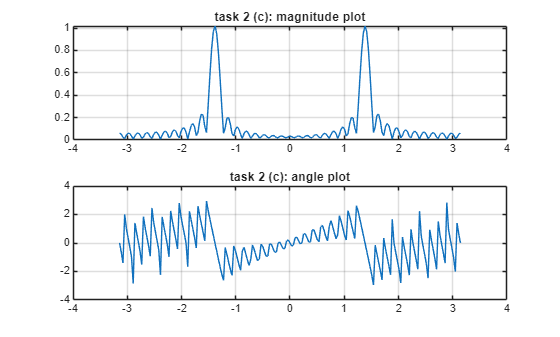

clc;
clear;
close all;

wc = 0.44*pi;
w = -pi:(pi/100):pi;

stopband_mask = (abs(w)<=0.3*pi | abs(w)>=0.7*pi);

l=0;
found = false;
while ~found
    l = l+1;
    n = 0:(l-1);
    h = 2/l * cos(wc*n);
    H = freqz(h, 1, w);
    H_mag = abs(H);
    H_max = max(H_mag);

    max_stopband = max(H_mag(stopband_mask));
    if max_stopband <= (H_max/10)
        found =true;
    end
end

figure;
subplot(2,1,1);
plot(w, H_mag), grid on
title("task 2 (c): magnitude plot")
subplot(2,1,2);
plot(w, angle(H)), grid on
title("task 2 (c): angle plot")



smallest_l_value = l

smallest_l_value = 37

## (d)

n_vec = 0:200; 
x = 10*cos(0.3*pi*n_vec) + 40*cos(0.44*pi*n_vec - pi/3) + 20*cos(0.7*pi*n_vec - pi/4);

%Find filter output y[n] using h from part (c)
y = conv(x, h);

fs = 2*pi;% sampling frequency
t = 0:(1/fs):(10-1/fs); % time vector
S= y;  %output acquired in step 1
n = length(S);
X = fft(S) ;
Y = fftshift(X);
fshift = (-n/2:n/2-1)*(fs/n); % zero-centered frequency range
figure;
plot(fshift,abs(Y)/n)
title("task 2 (d): funtion after filter applied to it")

our filter only allowed the outputs with the freq between the stop_band (40*cos(0.44*pi*n_vec - pi/3)) to pass and attenuated all of the other frequency (10*cos(0.3*pi*n_vec) ,  20*cos(0.7*pi*n_vec - pi/4))